# Phase Plane

## 1. Wild Type

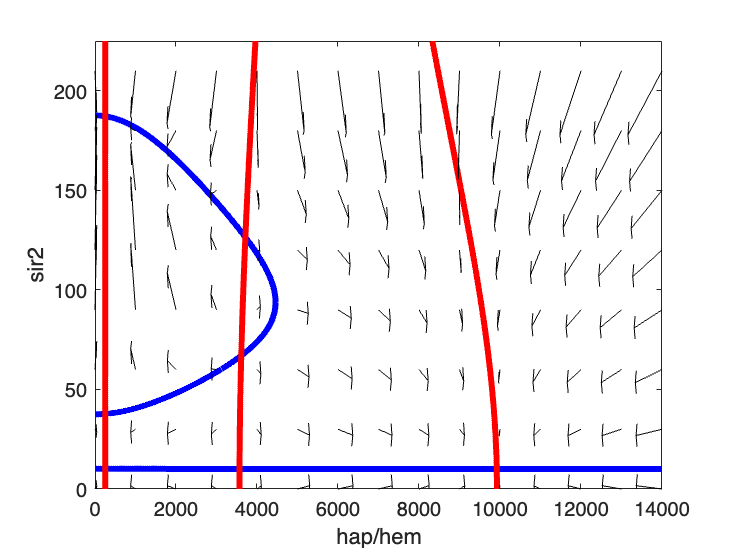

close all
clear

%% set parameters
k_hap_prod = 40;
k_hap_deg = 0.004;
k_hap_prod_base = 1;
KM_SonH = 280;
KM_pos = 4250;

Total = 225;
k_sir_prod = 0.02;
k_sir_deg = 0.004;
KM_HonS = 2200;
KM_pos2 = 90;
k_sir_prod_base = 0.04;

n1 = 2;
n2 = 4;
n3 = 2;
n4 = 4;

neg_strength1 = 0.05;
neg_strength2 = 0.65;

%% find the sir2 roots at steady state
for ii = 0:1400
    h(ii+1) = ii*10;
    neg_fac = (neg_strength1*h(ii+1)^n3+KM_HonS^n3)/(h(ii+1)^n3+KM_HonS^n3);
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
plot(h_line, s_line, 'b', 'LineWidth', 3)
hold on

%% find the hap roots at steady state
for ii = 0:Total
    s(ii+1) = ii;
    neg_fac2 = (neg_strength2*s(ii+1)^n1+KM_SonH^n1)/(s(ii+1)^n1+KM_SonH^n1);
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end
%%
%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'r', 'LineWidth', 3)

%% get the vector for quiver plot, and save data for later plotting with python 
h_2 = 0:1000:14000;
s_2 = 0:30:Total;
[X, Y] = meshgrid(h_2,s_2);

neg_fac = (neg_strength1*X.^n3+KM_HonS^n3)./(X.^n3+KM_HonS^n3);
ds = k_sir_prod*neg_fac.*(Y.^n4./(Y.^n4+KM_pos2^n4)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = (neg_strength2*Y.^n1+KM_SonH^n1)./(Y.^n1+KM_SonH^n1);
dh = k_hap_prod*neg_fac2.*(X.^n2./(X.^n2+KM_pos^n2)) + k_hap_prod_base - k_hap_deg*X;
% 
%%
hq = quiver(X,Y,dh,ds,'k');
hq.MaxHeadSize = 0.005;
hq.Head.LineStyle = 'solid';
xlabel('hap/hem');
ylabel('sir2')
ylim([0 Total])

save('./WT.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');

## 2. No Mutual Inhibition

close all
clear

%% set parameters
k_hap_prod = 40;
k_hap_deg = 0.004;
k_hap_prod_base = 1;
KM_SonH = 280;
KM_pos = 4250;

Total = 225;
k_sir_prod = 0.02;
k_sir_deg = 0.004;
KM_HonS = 2200;
KM_pos2 = 90;
k_sir_prod_base = 0.04;

n1 = 2;
n2 = 4;
n3 = 2;
n4 = 4;

neg_strength1 = 0.05;
neg_strength2 = 0.65;

%% find the sir2 roots at steady state
for ii = 0:1400
    h(ii+1) = ii*10;
    neg_fac = 1;
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
plot(h_line, s_line, 'b', 'LineWidth', 3)
hold on

%% find the hap roots at steady state
for ii = 0:Total
    s(ii+1) = ii;
    neg_fac2 = 1;
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end
%%
%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'r', 'LineWidth', 3)

%% get the vector for quiver plot, and save data for later plotting with python 
h_2 = 0:1000:14000;
s_2 = 0:30:Total;
[X, Y] = meshgrid(h_2,s_2);

neg_fac = 1;
ds = k_sir_prod*neg_fac.*(Y.^n4./(Y.^n4+KM_pos2^n4)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = 1;
dh = k_hap_prod*neg_fac2.*(X.^n2./(X.^n2+KM_pos^n2)) + k_hap_prod_base - k_hap_deg*X;
% 
%%
hq = quiver(X,Y,dh,ds,'k');
hq.MaxHeadSize = 0.005;
hq.Head.LineStyle = 'solid';
xlabel('hap/hem');
ylabel('sir2')
ylim([0 Total])
save('./no_mutual_inhibition.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');

## 3. Sir2 deletion

close all
clear

%% set parameters
k_hap_prod = 40;
k_hap_deg = 0.004;
k_hap_prod_base = 1;
KM_SonH = 280;
KM_pos = 4250;

Total = 20;
k_sir_prod = 0.02;
k_sir_deg = 0.004;
KM_HonS = 2200;
KM_pos2 = 90;
k_sir_prod_base = 0.04;

n1 = 2;
n2 = 4;
n3 = 2;
n4 = 4;

neg_strength1 = 0.05;
neg_strength2 = 0.65;

%% find the sir2 roots at steady state
for ii = 0:1400
    h(ii+1) = ii*10;
    neg_fac = (neg_strength1*h(ii+1)^n3+KM_HonS^n3)/(h(ii+1)^n3+KM_HonS^n3);
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
plot(h_line, s_line, 'b', 'LineWidth', 3)
hold on

%% find the hap roots at steady state
for ii = 0:200
    s(ii+1) = ii;
    neg_fac2 = (neg_strength2*s(ii+1)^n1+KM_SonH^n1)/(s(ii+1)^n1+KM_SonH^n1);
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end
%%
%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'r', 'LineWidth', 3)

%% get the vector for quiver plot, and save data for later plotting with python 
h_2 = 0:1000:14000;
s_2 = 0:30:200;
[X, Y] = meshgrid(h_2,s_2);

neg_fac = (neg_strength1*X.^n3+KM_HonS^n3)./(X.^n3+KM_HonS^n3);
ds = k_sir_prod*neg_fac.*(Y.^n4./(Y.^n4+KM_pos2^n4)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = (neg_strength2*Y.^n1+KM_SonH^n1)./(Y.^n1+KM_SonH^n1);
dh = k_hap_prod*neg_fac2.*(X.^n2./(X.^n2+KM_pos^n2)) + k_hap_prod_base - k_hap_deg*X;
% 
%%
hq = quiver(X,Y,dh,ds,'k');
hq.MaxHeadSize = 0.005;
hq.Head.LineStyle = 'solid';
xlabel('hap/hem');
ylabel('sir2')
ylim([-20 210])
save('./sir2.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');

## 4. Hap4 deletion

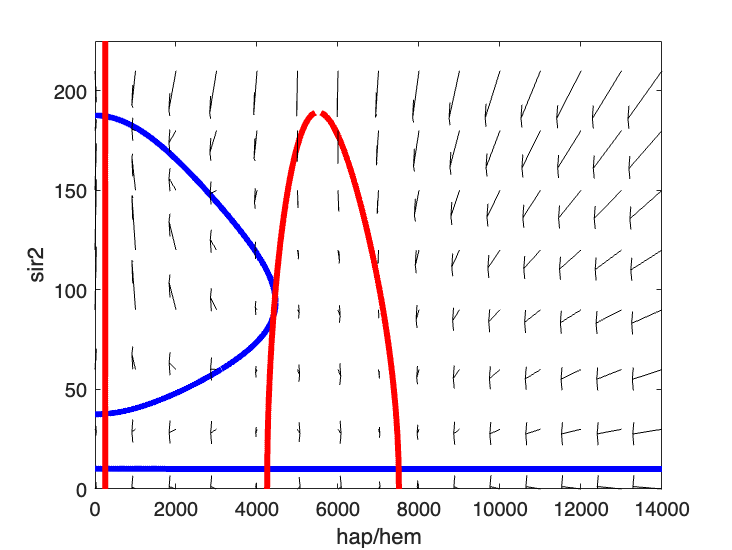

close all
clear

%% set parameters
k_hap_prod = 30;
k_hap_deg = 0.004;
k_hap_prod_base = 1;
KM_SonH = 280;
KM_pos = 4250;

Total = 225;
k_sir_prod = 0.02;
k_sir_deg = 0.004;
KM_HonS = 2200;
KM_pos2 = 90;
k_sir_prod_base = 0.04;

n1 = 2;
n2 = 4;
n3 = 2;
n4 = 4;

neg_strength1 = 0.05;
neg_strength2 = 0.65;

%% find the sir2 roots at steady state
for ii = 0:1400
    h(ii+1) = ii*10;
    neg_fac = (neg_strength1*h(ii+1)^n3+KM_HonS^n3)/(h(ii+1)^n3+KM_HonS^n3);
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
plot(h_line, s_line, 'b', 'LineWidth', 3)
hold on

%% find the hap roots at steady state
for ii = 0:Total
    s(ii+1) = ii;
    neg_fac2 = (neg_strength2*s(ii+1)^n1+KM_SonH^n1)/(s(ii+1)^n1+KM_SonH^n1);
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end
%%
%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'r', 'LineWidth', 3)

%% get the vector for quiver plot, and save data for later plotting with python 
h_2 = 0:1000:14000;
s_2 = 0:30:Total;
[X, Y] = meshgrid(h_2,s_2);

neg_fac = (neg_strength1*X.^n3+KM_HonS^n3)./(X.^n3+KM_HonS^n3);
ds = k_sir_prod*neg_fac.*(Y.^n4./(Y.^n4+KM_pos2^n4)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = (neg_strength2*Y.^n1+KM_SonH^n1)./(Y.^n1+KM_SonH^n1);
dh = k_hap_prod*neg_fac2.*(X.^n2./(X.^n2+KM_pos^n2)) + k_hap_prod_base - k_hap_deg*X;
% 
%%
hq = quiver(X,Y,dh,ds,'k');
hq.MaxHeadSize = 0.005;
hq.Head.LineStyle = 'solid';
xlabel('hap/hem');
ylabel('sir2')
ylim([0 Total])

save('./hap4.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');

## 5. Sir2 double expression

close all
clear

%% set parameters
k_hap_prod = 40;
k_hap_deg = 0.004;
k_hap_prod_base = 1;
KM_SonH = 280;
KM_pos = 4250;

Total = 450;
k_sir_prod = 0.02;
k_sir_deg = 0.004;
KM_HonS = 2200;
KM_pos2 = 90;
k_sir_prod_base = 0.04;

n1 = 2;
n2 = 4;
n3 = 2;
n4 = 4;

neg_strength1 = 0.05;
neg_strength2 = 0.65;

%% find the sir2 roots at steady state
for ii = 0:1400
    h(ii+1) = ii*10;
    neg_fac = (neg_strength1*h(ii+1)^n3+KM_HonS^n3)/(h(ii+1)^n3+KM_HonS^n3);
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
plot(h_line, s_line, 'b', 'LineWidth', 3)
hold on

%% find the hap roots at steady state
for ii = 0:Total
    s(ii+1) = ii;
    neg_fac2 = (neg_strength2*s(ii+1)^n1+KM_SonH^n1)/(s(ii+1)^n1+KM_SonH^n1);
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end
%%
%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'r', 'LineWidth', 3)

%% get the vector for quiver plot, and save data for later plotting with python 
h_2 = 0:1000:14000;
s_2 = 0:30:Total;
[X, Y] = meshgrid(h_2,s_2);

neg_fac = (neg_strength1*X.^n3+KM_HonS^n3)./(X.^n3+KM_HonS^n3);
ds = k_sir_prod*neg_fac.*(Y.^n4./(Y.^n4+KM_pos2^n4)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = (neg_strength2*Y.^n1+KM_SonH^n1)./(Y.^n1+KM_SonH^n1);
dh = k_hap_prod*neg_fac2.*(X.^n2./(X.^n2+KM_pos^n2)) + k_hap_prod_base - k_hap_deg*X;
% 
%%
hq = quiver(X,Y,dh,ds,'k');
hq.MaxHeadSize = 0.005;
hq.Head.LineStyle = 'solid';
xlabel('hap/hem');
ylabel('sir2')
ylim([0 Total])
save('./sir_double.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');

## 6. Sir2 Double expression/Hap overexpression

close all
clear

%% set parameters
k_hap_prod = 40;
k_hap_deg = 0.004;
k_hap_prod_base = 5;
KM_SonH = 280;
KM_pos = 4250;

Total = 450;
k_sir_prod = 0.02;
k_sir_deg = 0.004;
KM_HonS = 2200;
KM_pos2 = 90;
k_sir_prod_base = 0.04;

n1 = 2;
n2 = 4;
n3 = 2;
n4 = 4;

neg_strength1 = 0.05;
neg_strength2 = 0.65;

%% find the sir2 roots at steady state
for ii = 0:1400
    h(ii+1) = ii*10;
    neg_fac = (neg_strength1*h(ii+1)^n3+KM_HonS^n3)/(h(ii+1)^n3+KM_HonS^n3);
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
plot(h_line, s_line, 'b', 'LineWidth', 3)
hold on

%% find the hap roots at steady state
for ii = 0:Total
    s(ii+1) = ii;
    neg_fac2 = (neg_strength2*s(ii+1)^n1+KM_SonH^n1)/(s(ii+1)^n1+KM_SonH^n1);
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end
%%
%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'r', 'LineWidth', 3)

%% get the vector for quiver plot, and save data for later plotting with python 
h_2 = 0:1000:14000;
s_2 = 0:30:Total;
[X, Y] = meshgrid(h_2,s_2);

neg_fac = (neg_strength1*X.^n3+KM_HonS^n3)./(X.^n3+KM_HonS^n3);
ds = k_sir_prod*neg_fac.*(Y.^n4./(Y.^n4+KM_pos2^n4)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = (neg_strength2*Y.^n1+KM_SonH^n1)./(Y.^n1+KM_SonH^n1);
dh = k_hap_prod*neg_fac2.*(X.^n2./(X.^n2+KM_pos^n2)) + k_hap_prod_base - k_hap_deg*X;
% 
%%
hq = quiver(X,Y,dh,ds,'k');
hq.MaxHeadSize = 0.005;
hq.Head.LineStyle = 'solid';
xlabel('hap/hem');
ylabel('sir2')
ylim([0 Total])
save('./all_over.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');